# Redes Neuronales

### Tarea 3: Dataset Computer Hardware

`Realizado por:`` David Fabián Cevallos Salas`

`Fecha:`` 2023-07-25`

En esta tarea analizaremos el Dataset Computer Hardware a través de un árbol de regresión.

El dataset se encuentra disponible en: [http://archive.ics.uci.edu/dataset/29/computer+hardware](https://colab.research.google.com/corgiredirector?site=http%3A%2F%2Farchive.ics.uci.edu%2Fdataset%2F29%2Fcomputer%2Bhardware&link_redirector=1), posee 299 observaciones y 9 descriptores.

El laboratorio comprende dos partes. En la primera parte se construye un árbol de regresión considerando la variable 1 (Vendor name) y descartando la variable 2 (Model name), pues ésta última no posee información de utilidad. En la segunda parte se descartan tanto la variable 1 como la variable 2. La idea principal es corroborar si la variable 1 contribuye o no al modelo.

% Redes Neuronales
% Tarea 3: Dataset Computer Hardware
clc; 
clear;
close all;
rng(0);
warning("off","all")

% Lectura de datos
T = readtable("machine.txt","ReadVariableNames",false);

% Limpieza de datos
T(T.Var1=="adviser",1)={'1'};
T(T.Var1=="amdahl",1)={'2'};
T(T.Var1=="apollo",1)={'3'};
T(T.Var1=="basf",1)={'4'};
T(T.Var1=="bti",1)={'5'};
T(T.Var1=="burroughs",1)={'6'};
T(T.Var1=="c.r.d",1)={'7'};
T(T.Var1=="cambex",1)={'8'};
T(T.Var1=="cdc",1)={'9'};
T(T.Var1=="dec",1)={'10'};
T(T.Var1=="dg",1)={'11'};
T(T.Var1=="formation",1)={'12'};
T(T.Var1=="four-phase",1)={'13'};
T(T.Var1=="gould",1)={'14'};
T(T.Var1=="harris",1)={'15'};
T(T.Var1=="honeywell",1)={'16'};
T(T.Var1=="hp",1)={'17'};
T(T.Var1=="ibm",1)={'18'};
T(T.Var1=="ipl",1)={'19'};
T(T.Var1=="magnuson",1)={'20'};
T(T.Var1=="microdata",1)={'21'};
T(T.Var1=="nas",1)={'22'};
T(T.Var1=="ncr",1)={'23'};
T(T.Var1=="nixdorf",1)={'24'};
T(T.Var1=="perkin-elmer",1)={'25'};
T(T.Var1=="prime",1)={'26'};
T(T.Var1=="siemens",1)={'27'};
T(T.Var1=="sperry",1)={'28'};
T(T.Var1=="sratus",1)={'29'};
T(T.Var1=="wang",1)={'30'};
T.Var1 = str2double(T.Var1);

% Parte 1: Árbol de regresión considerando la variable 1 (Vendor name) y
% y descartando la variable 2 (model name)
fprintf("-----------------------------------------------")

-----------------------------------------------

fprintf("Resultados Parte 1")

Resultados Parte 1

fprintf("Considerando variable 1 y descartando variable 2")

Considerando variable 1 y descartando variable 2

fprintf("-----------------------------------------------")

-----------------------------------------------

----------------------------------------------
Resultados para Fold Nro. 1
----------------------------------------------
Valor MSE = 956.2159
Diagrama de árbol de regresión

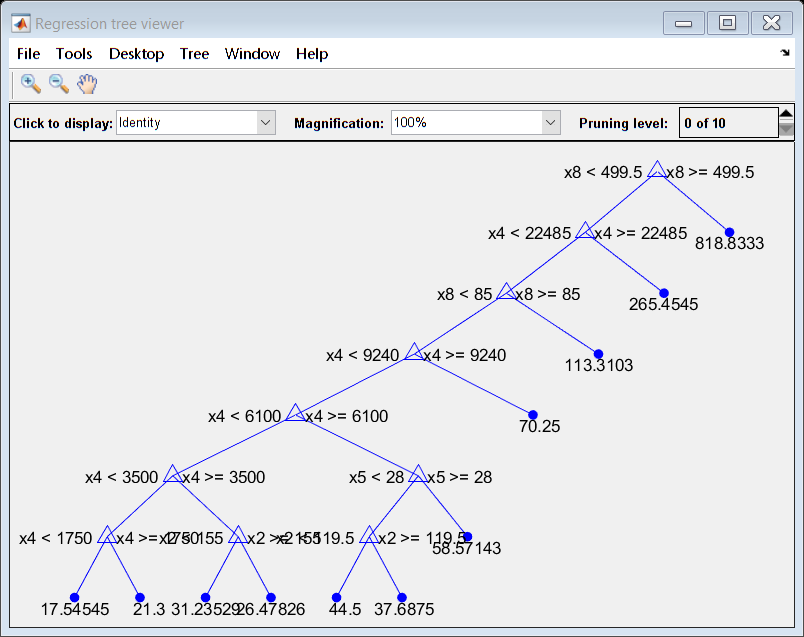

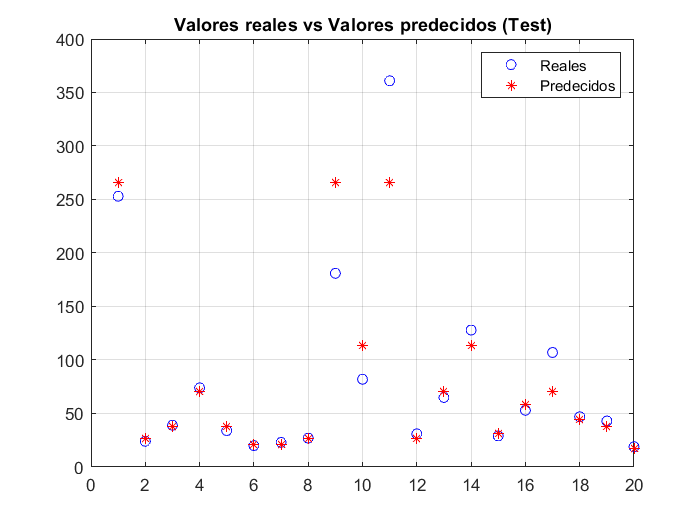

----------------------------------------------
Resultados para Fold Nro. 2
----------------------------------------------
Valor MSE = 1098.8330
Diagrama de árbol de regresión

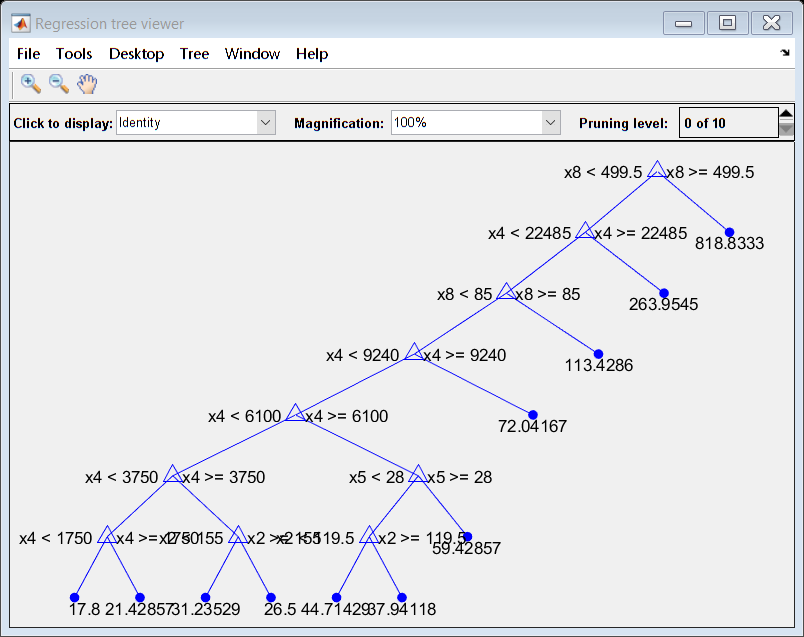

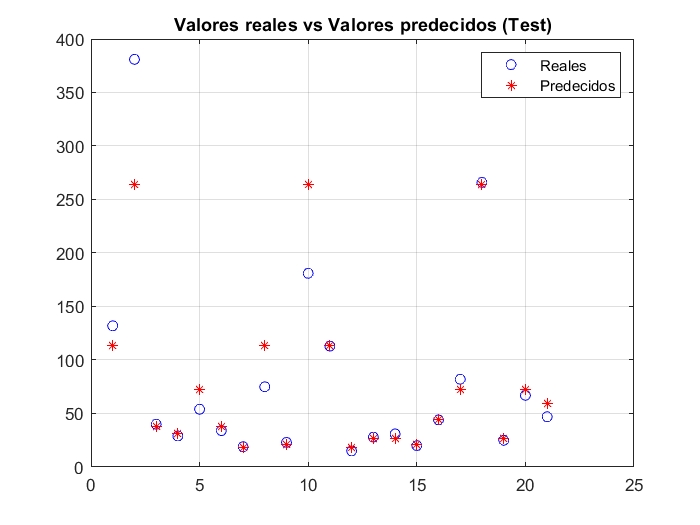

----------------------------------------------
Resultados para Fold Nro. 3
----------------------------------------------
Valor MSE = 9507.9741
Diagrama de árbol de regresión

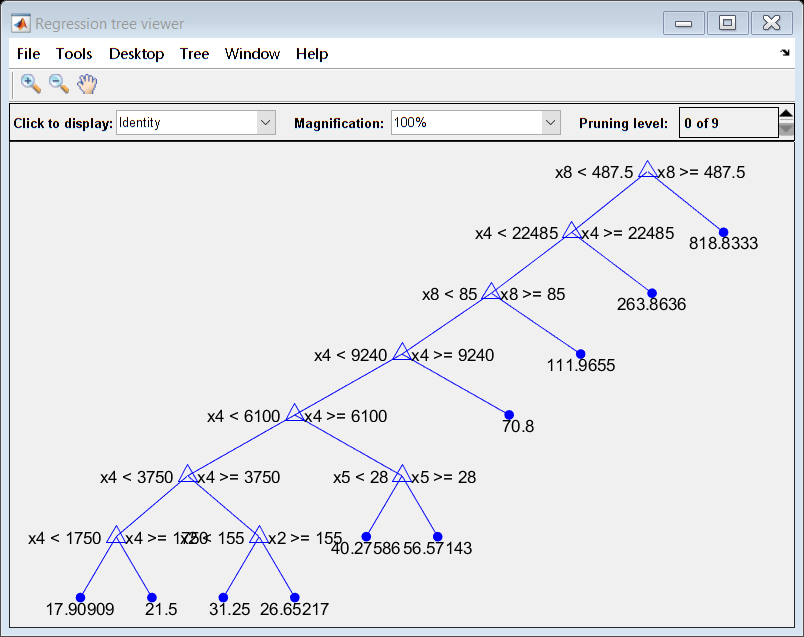

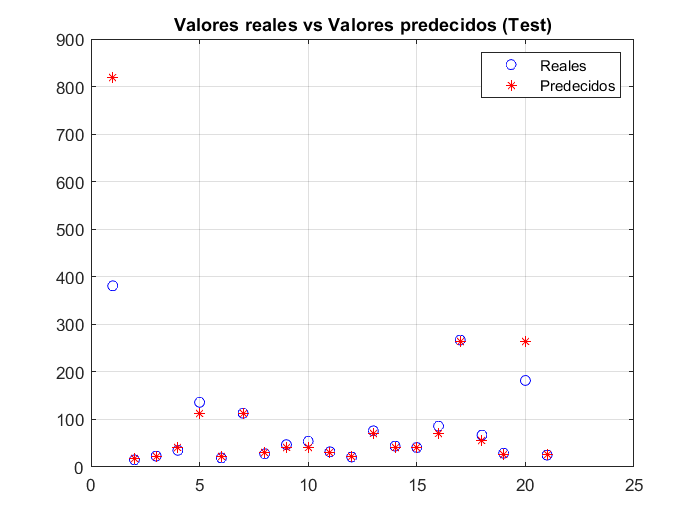

----------------------------------------------
Resultados para Fold Nro. 4
----------------------------------------------
Valor MSE = 1340.6773
Diagrama de árbol de regresión

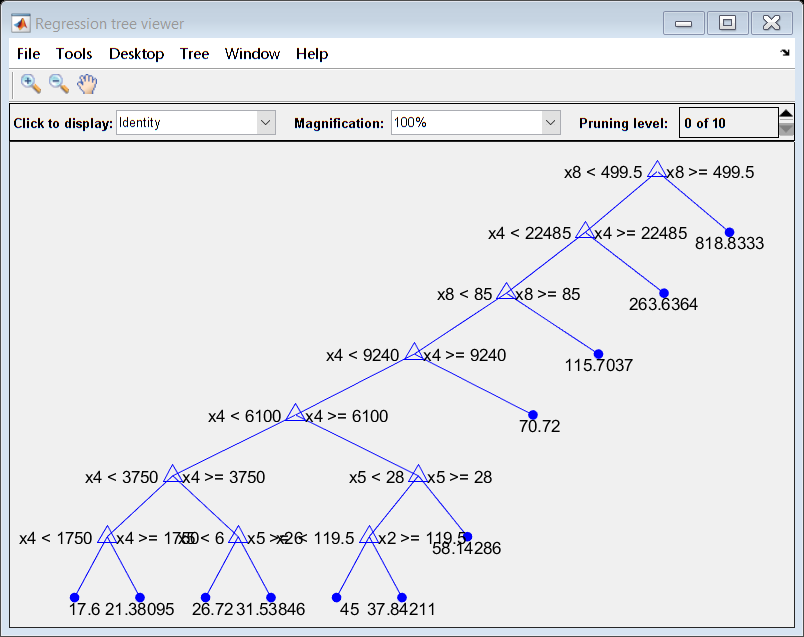

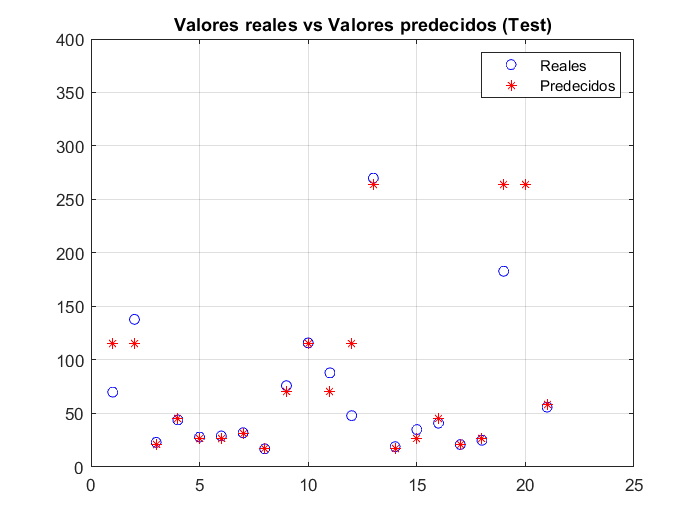

----------------------------------------------
Resultados para Fold Nro. 5
----------------------------------------------
Valor MSE = 11069.9763
Diagrama de árbol de regresión

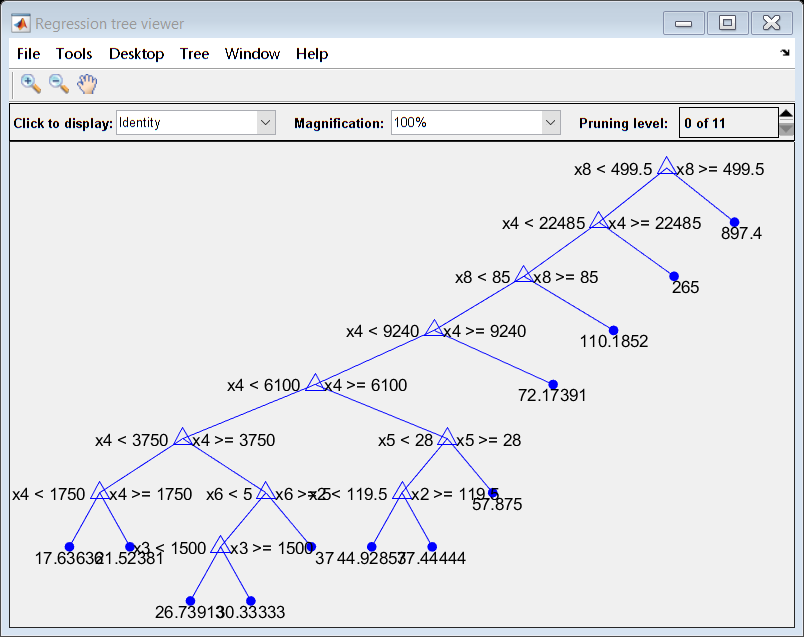

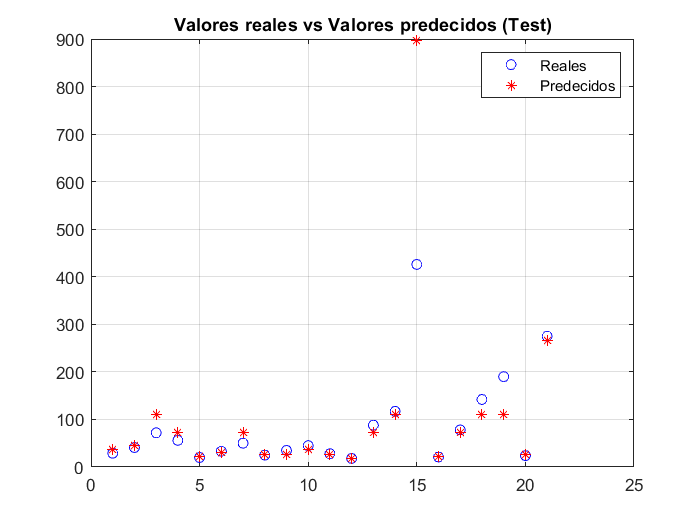

----------------------------------------------
Resultados para Fold Nro. 6
----------------------------------------------
Valor MSE = 6124.5472
Diagrama de árbol de regresión

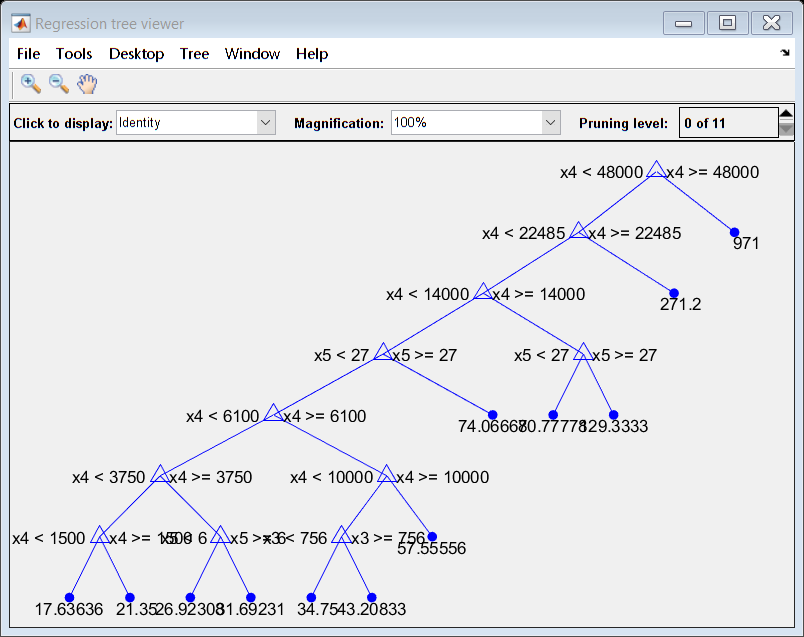

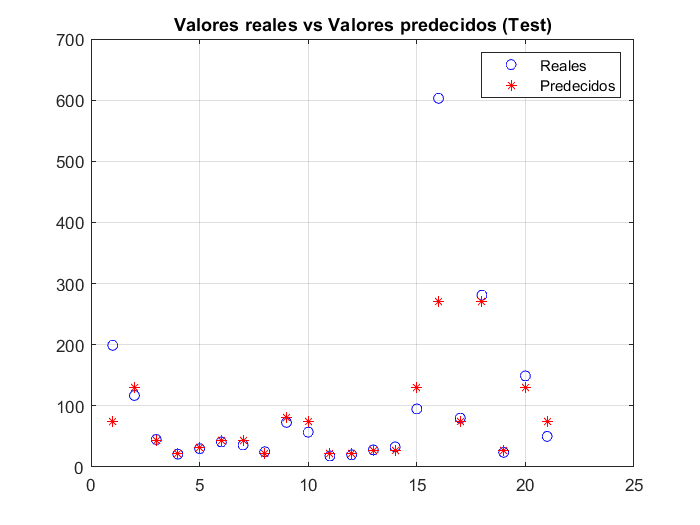

----------------------------------------------
Resultados para Fold Nro. 7
----------------------------------------------
Valor MSE = 1226.0386
Diagrama de árbol de regresión

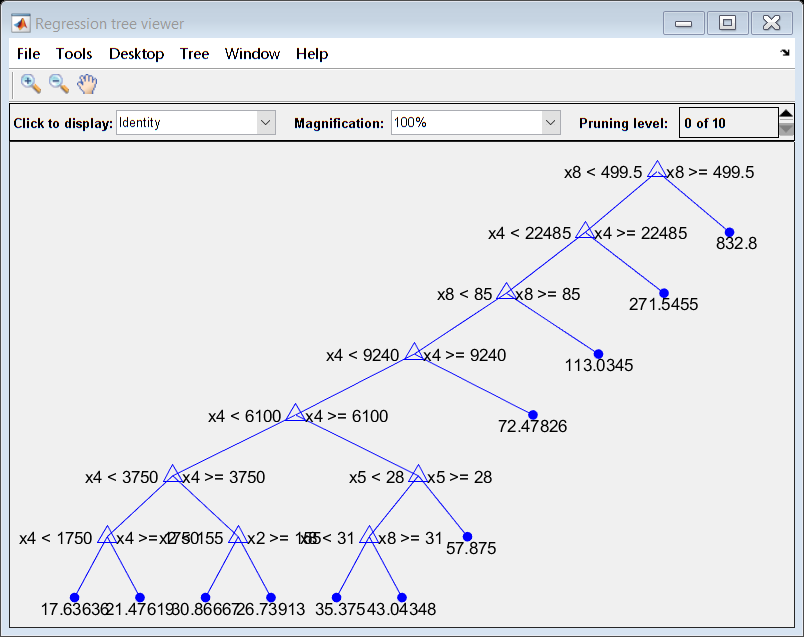

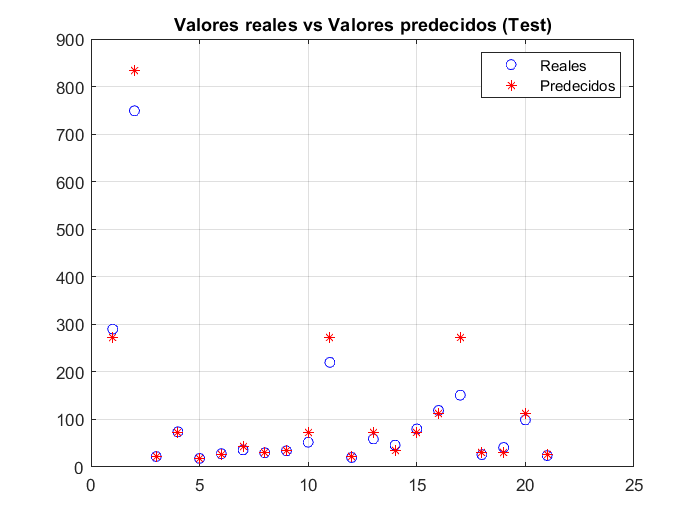

----------------------------------------------
Resultados para Fold Nro. 8
----------------------------------------------
Valor MSE = 2205.6255
Diagrama de árbol de regresión

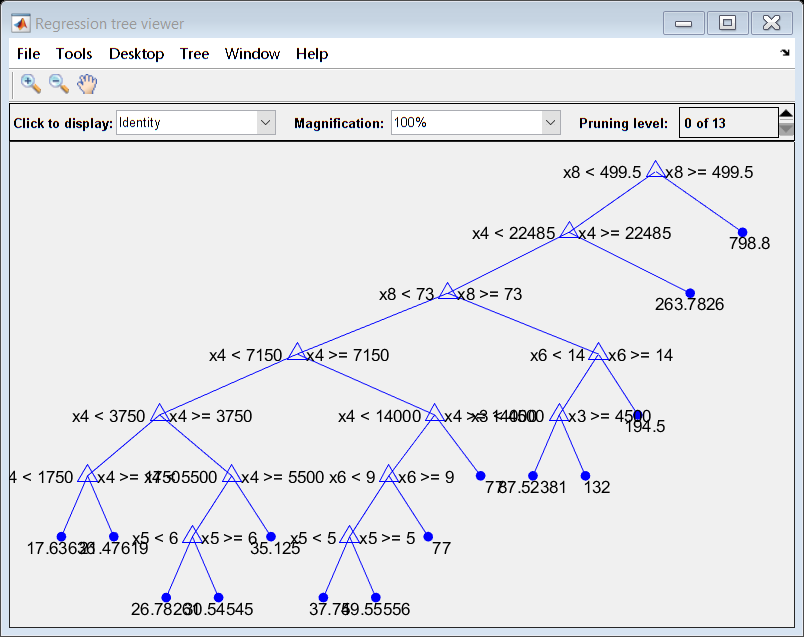

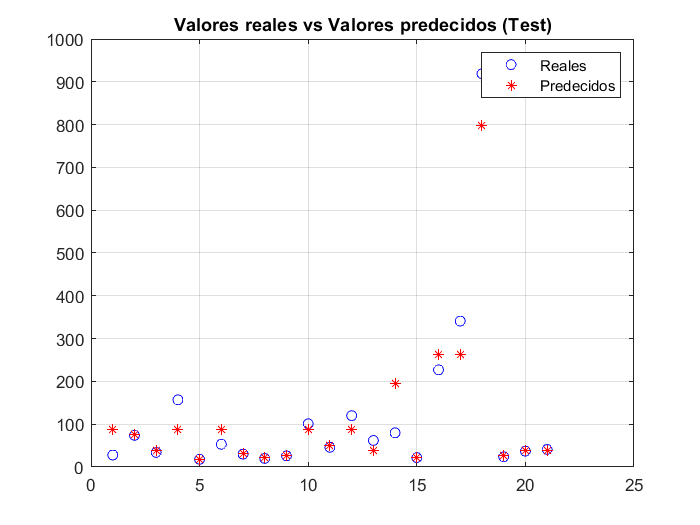

----------------------------------------------
Resultados para Fold Nro. 9
----------------------------------------------
Valor MSE = 2781.0734
Diagrama de árbol de regresión

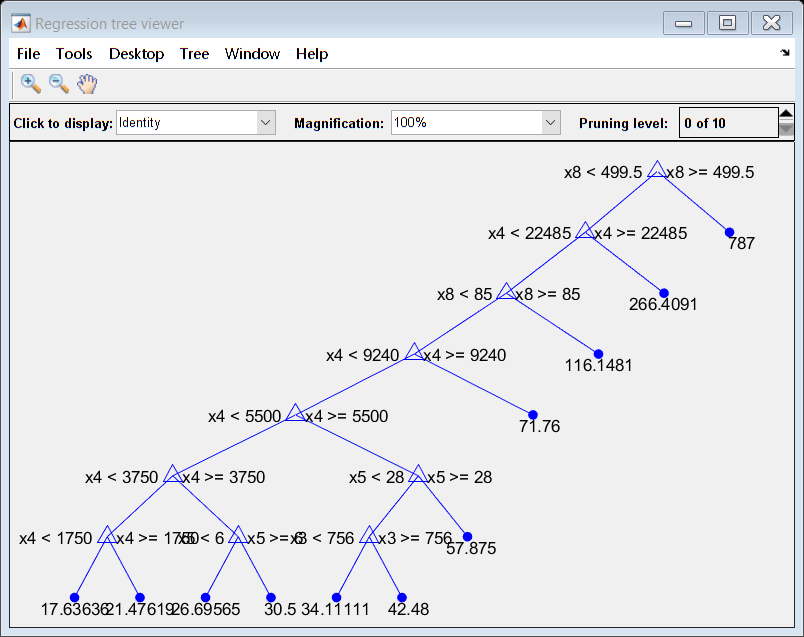

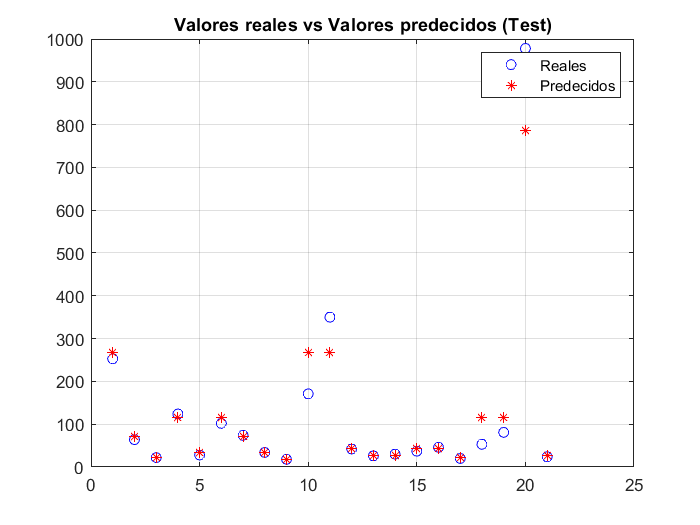

----------------------------------------------
Resultados para Fold Nro. 10
----------------------------------------------
Valor MSE = 23511.0938
Diagrama de árbol de regresión

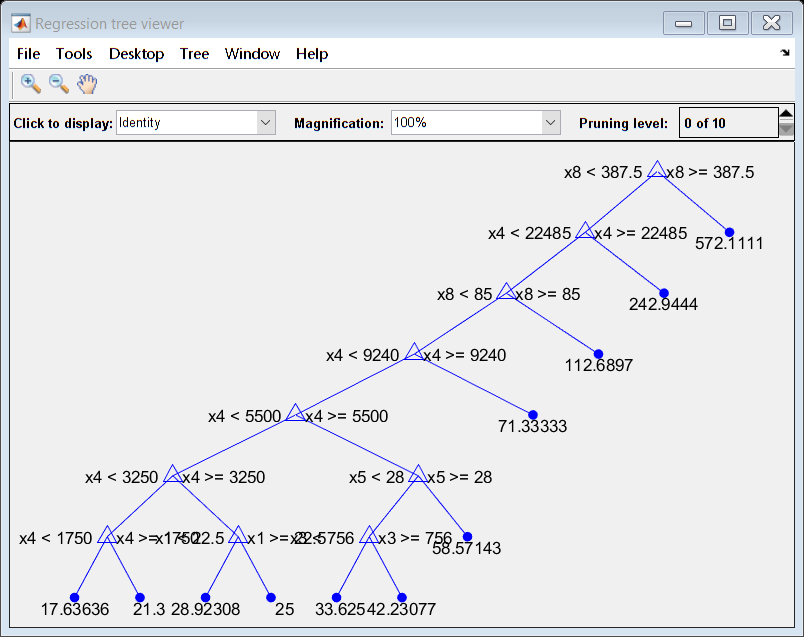

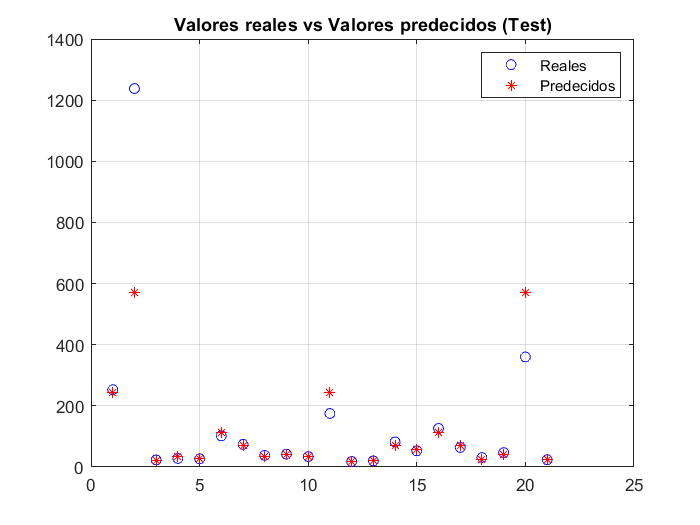


----------------------------------------------
Error Cuadrático Medio final 5982.2055
----------------------------------------------


X = table2array(T(:,[1,3:9]));
Y = table2array(T(:,10));
mean_mse_p1 = calcularMSE(X, Y);


% Parte 2: Árbol de regresión descartando la variable 1 (Vendor name) y
% la variable 2 (model name)
fprintf("-----------------------------------------------")

-----------------------------------------------

fprintf("Resultados Parte 2")

Resultados Parte 2

fprintf("Descartando la variable 1 y la variable 2")

Descartando la variable 1 y la variable 2

fprintf("-----------------------------------------------")

-----------------------------------------------

----------------------------------------------
Resultados para Fold Nro. 1
----------------------------------------------
Valor MSE = 943.3488
Diagrama de árbol de regresión

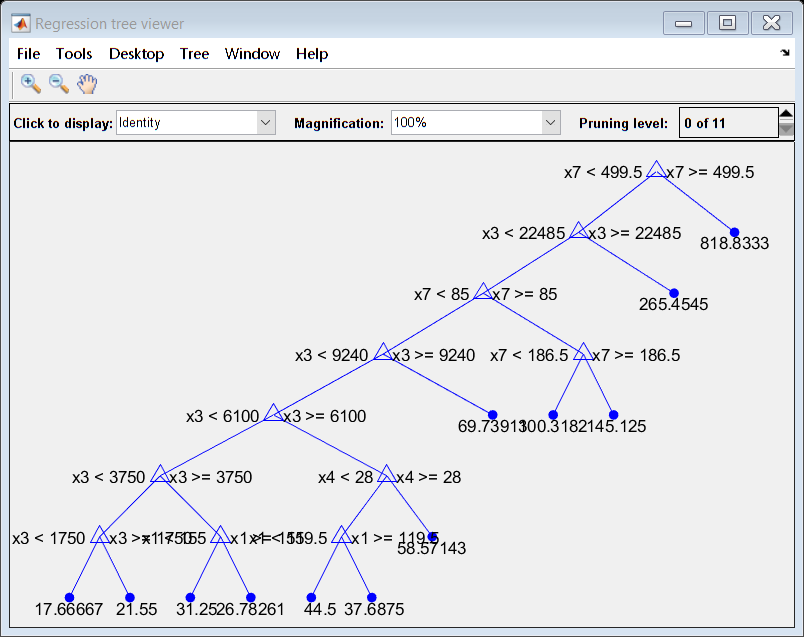

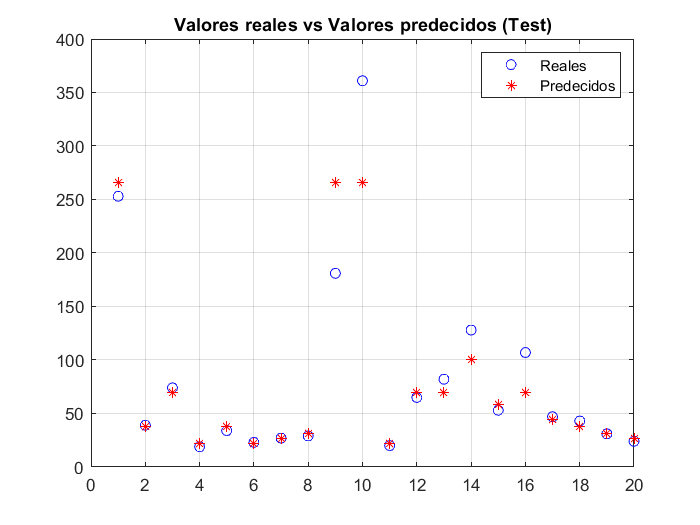

----------------------------------------------
Resultados para Fold Nro. 2
----------------------------------------------
Valor MSE = 1093.5287
Diagrama de árbol de regresión

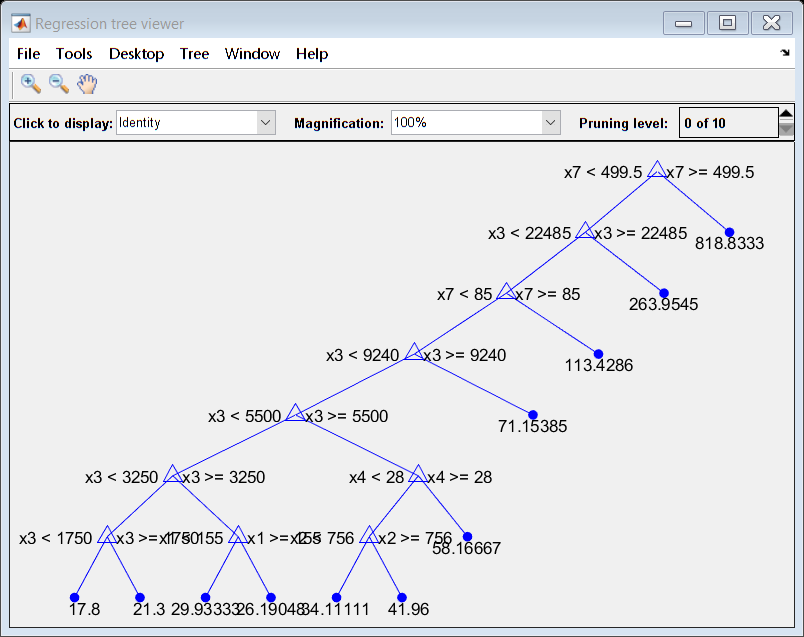

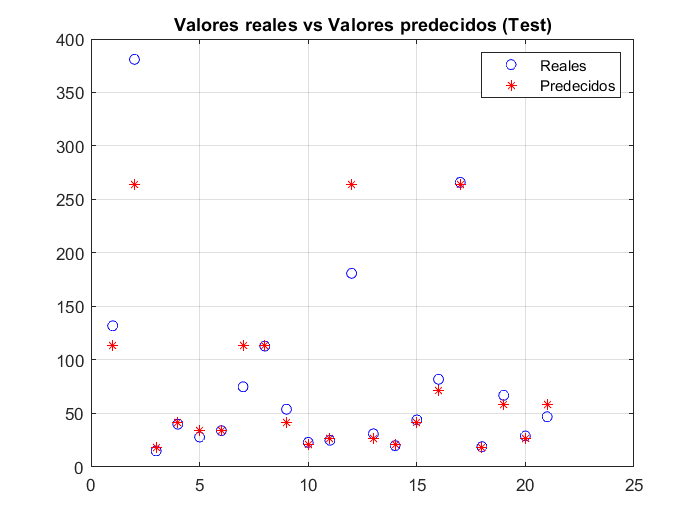

----------------------------------------------
Resultados para Fold Nro. 3
----------------------------------------------
Valor MSE = 9512.2522
Diagrama de árbol de regresión

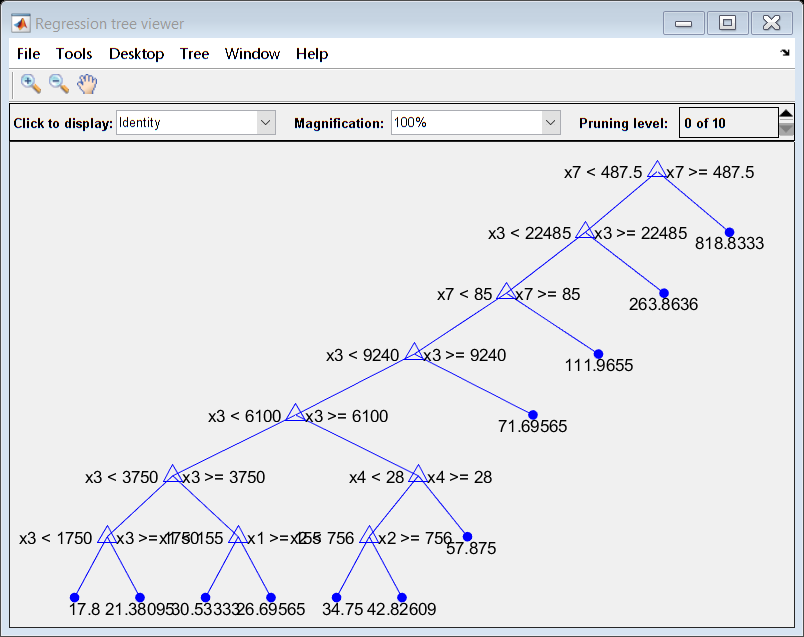

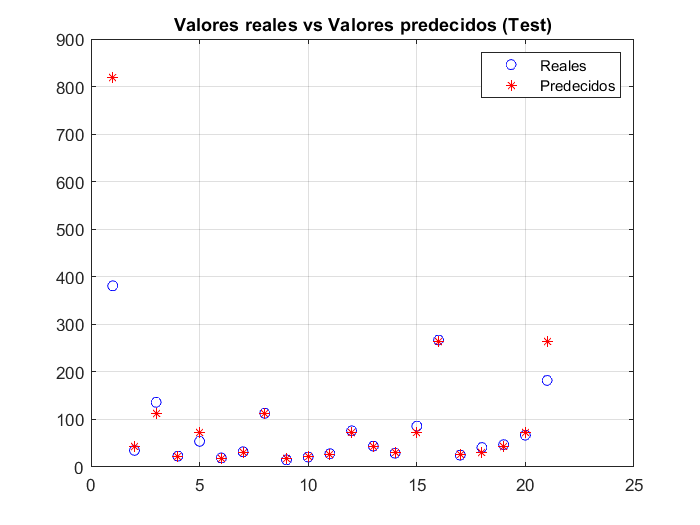

----------------------------------------------
Resultados para Fold Nro. 4
----------------------------------------------
Valor MSE = 1350.7145
Diagrama de árbol de regresión

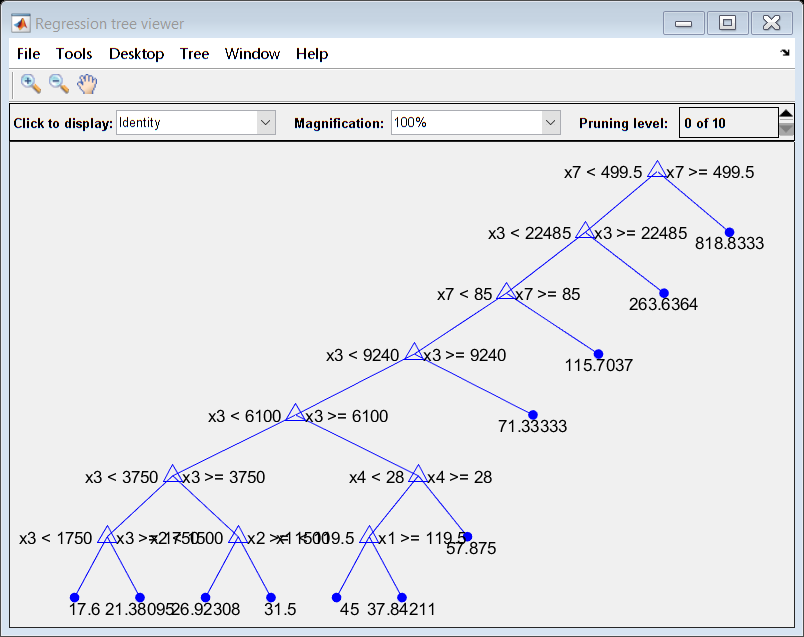

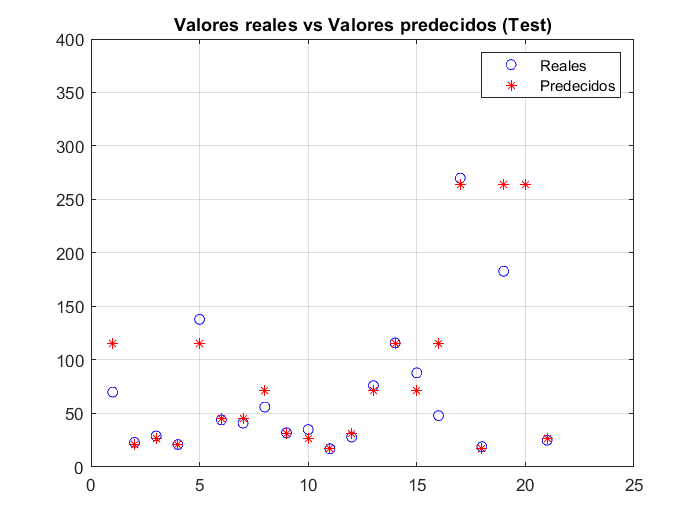

----------------------------------------------
Resultados para Fold Nro. 5
----------------------------------------------
Valor MSE = 11057.3434
Diagrama de árbol de regresión

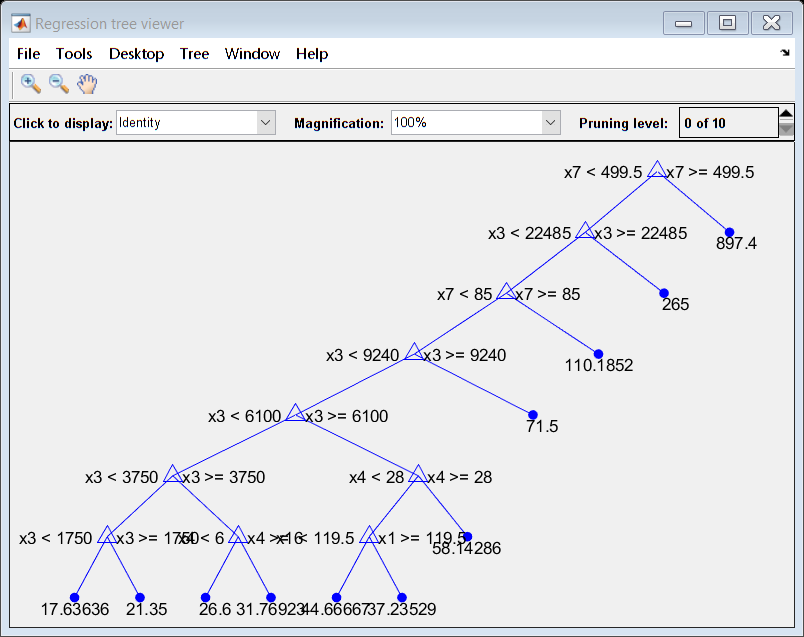

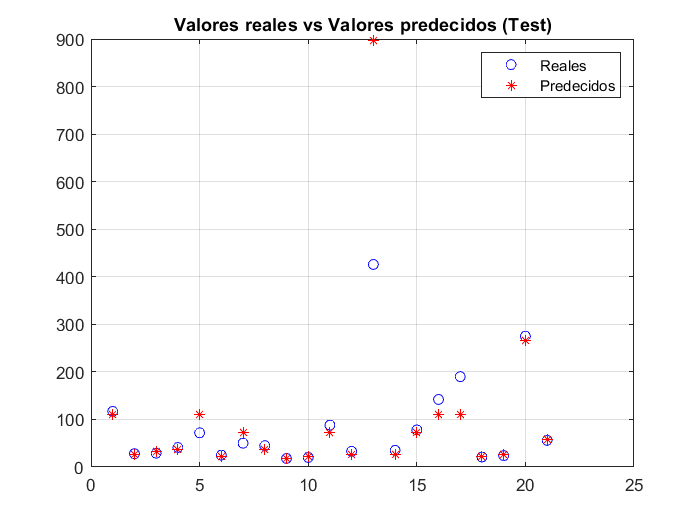

----------------------------------------------
Resultados para Fold Nro. 6
----------------------------------------------
Valor MSE = 6121.9891
Diagrama de árbol de regresión

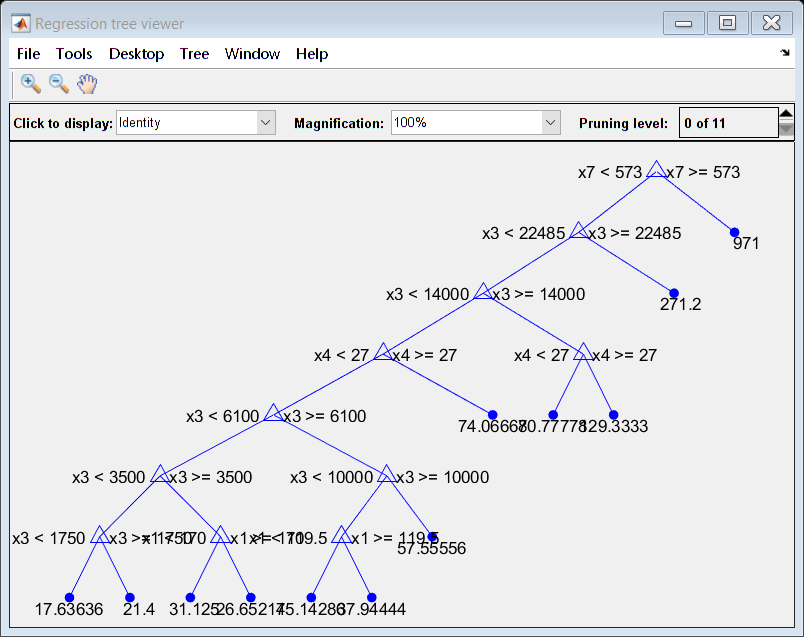

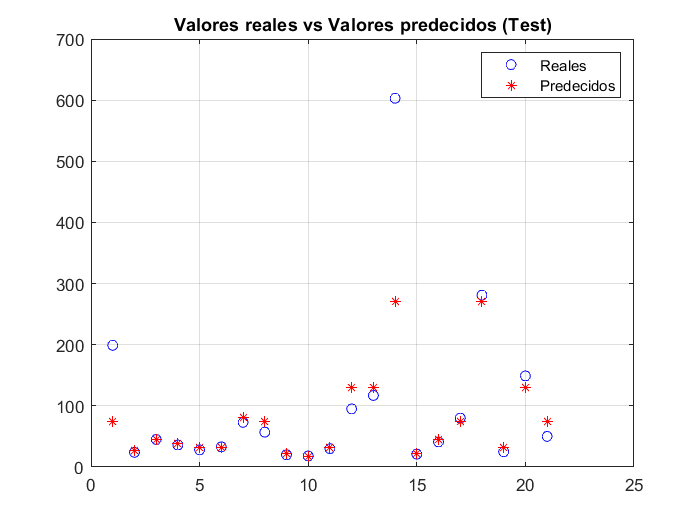

----------------------------------------------
Resultados para Fold Nro. 7
----------------------------------------------
Valor MSE = 1245.3957
Diagrama de árbol de regresión

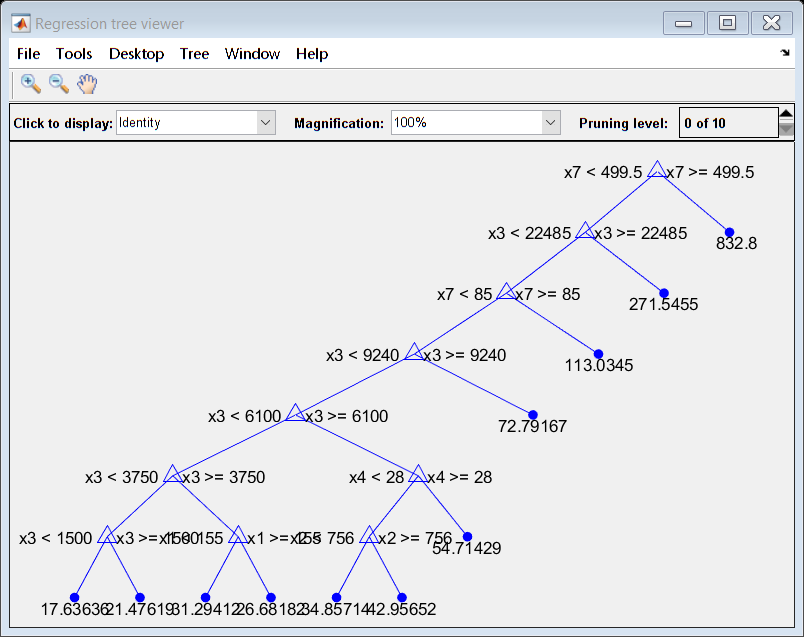

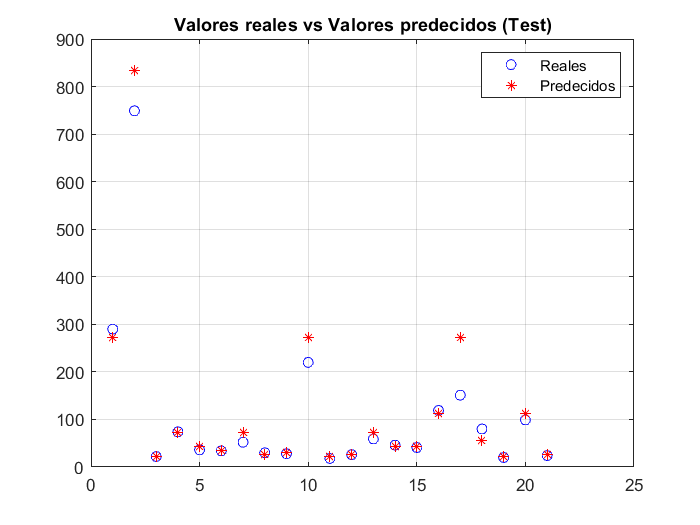

----------------------------------------------
Resultados para Fold Nro. 8
----------------------------------------------
Valor MSE = 1327.8362
Diagrama de árbol de regresión

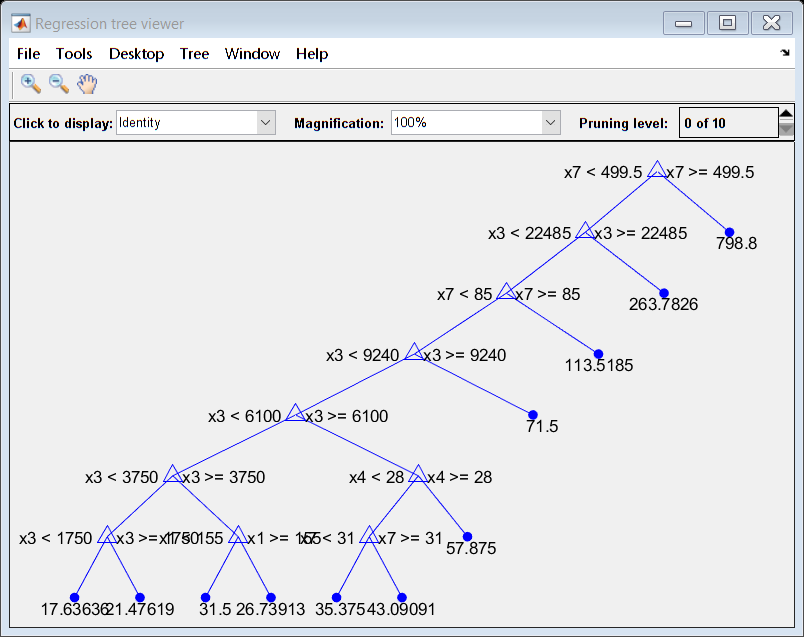

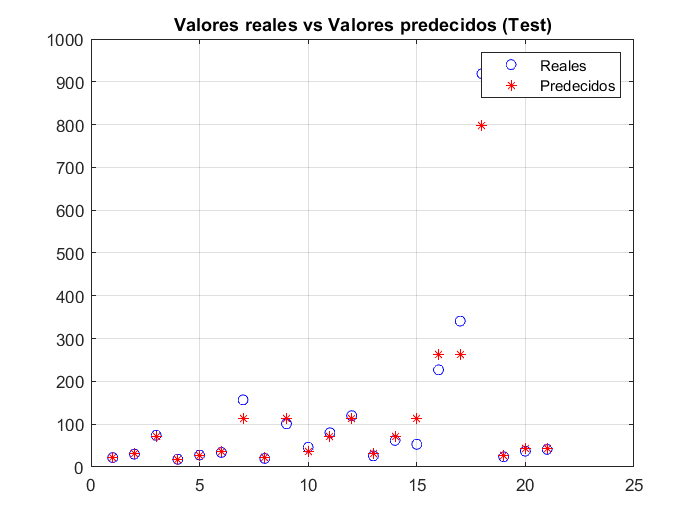

----------------------------------------------
Resultados para Fold Nro. 9
----------------------------------------------
Valor MSE = 2584.0268
Diagrama de árbol de regresión

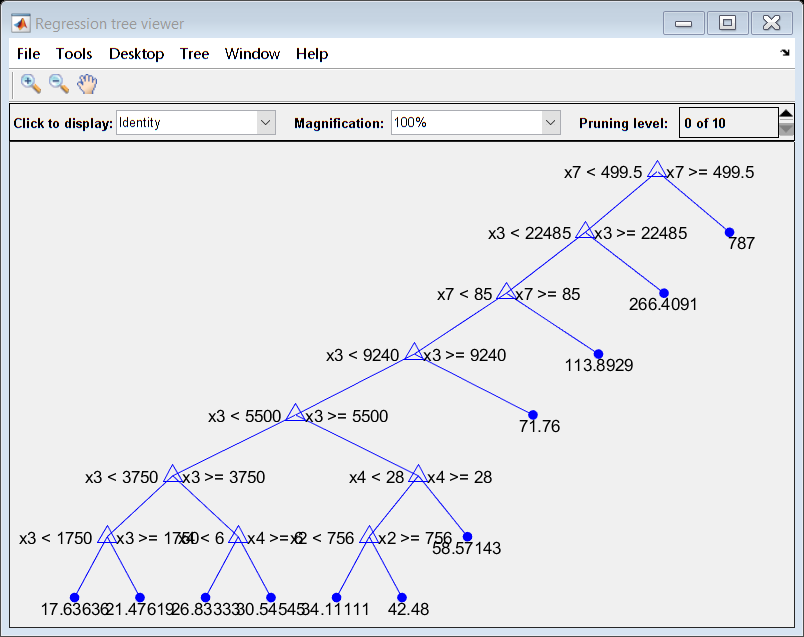

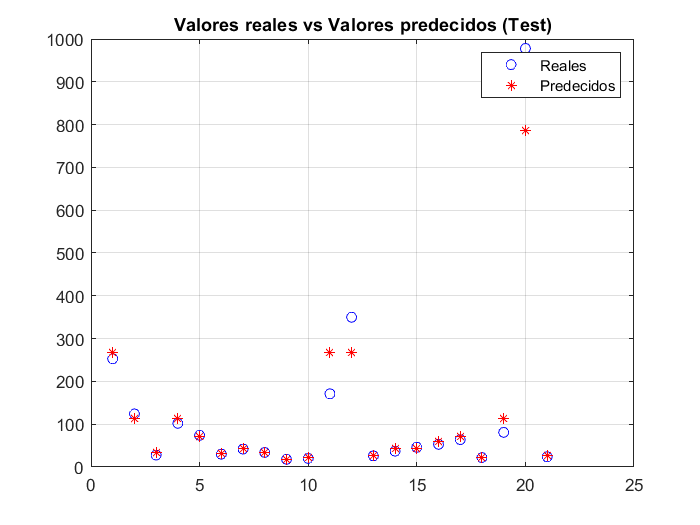

----------------------------------------------
Resultados para Fold Nro. 10
----------------------------------------------
Valor MSE = 23716.8691
Diagrama de árbol de regresión

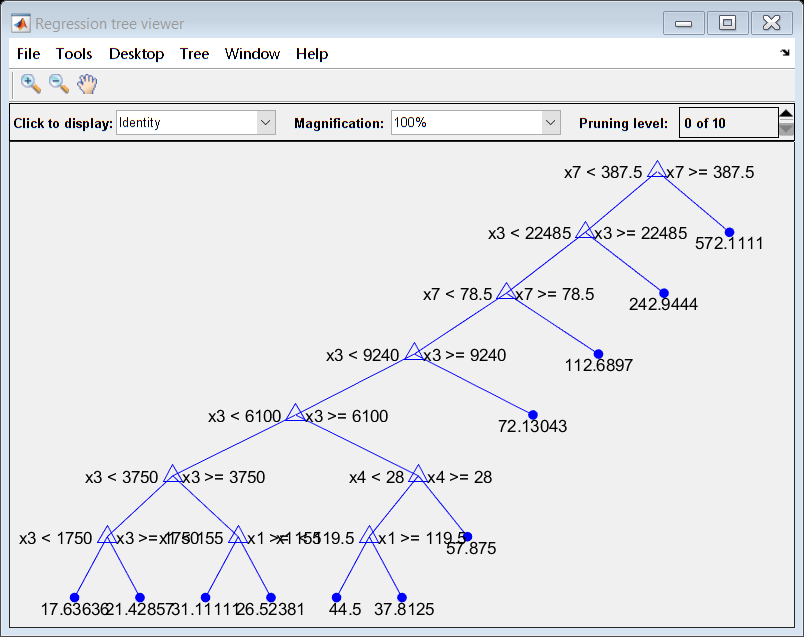

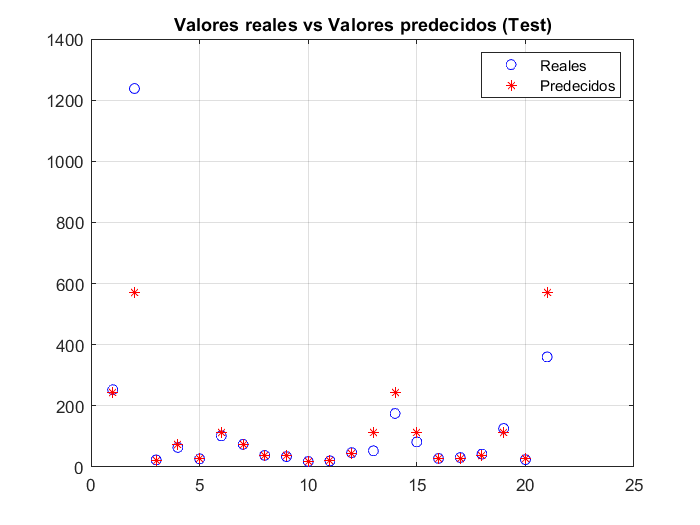


----------------------------------------------
Error Cuadrático Medio final 5895.3304
----------------------------------------------


X = table2array(T(:,3:9));
mean_mse_p2 = calcularMSE(X, Y);

function mean_mse = calcularMSE(X, Y)
    % Estrategia k-folding
    CVO = cvpartition(Y,"k",10);
    num_pruebas = CVO.NumTestSets;
    total_mse = 0;
        
    for i = 1:num_pruebas
        fprintf("----------------------------------------------")
        fprintf("\nResultados para Fold Nro. %d", i)
        fprintf("\n----------------------------------------------")
        % Indices de training y test
        trIdx = CVO.training(i);
        teIdx = CVO.test(i);
        % Árbol de regresión
        tree = fitrtree(X(trIdx,:),Y(trIdx,:), "MinParentSize", 30);
        % Vector de predicciones y cálculo de MSE
        Ypred = predict(tree, X(teIdx,:));
        fold_mse = mse(Y(teIdx), Ypred);
        fprintf("\nValor MSE = %.4f", fold_mse)
        total_mse = total_mse + fold_mse;
        % Diagrama del árbol de regresión empleado
        fprintf("\nDiagrama de árbol de regresión");
        view(tree,"mode","graph")
        % Diagrama de valores reales contra valores predecidos
        figure;
        plot(Y(teIdx), "ob")
        hold on;
        plot(Ypred,"*r")
        grid on;
        title("Valores reales vs Valores predecidos (Test)");
        legend("Reales", "Predecidos");
        hold off;
    end
    
    % Mean MSE para el ejercicio
    mean_mse = total_mse/num_pruebas;
    fprintf("\n----------------------------------------------")
    fprintf("\nError Cuadrático Medio final %.4f", mean_mse);
    fprintf("\n----------------------------------------------")
end

**Conclusión:**

Se puede concluir que la variable número 1 correspondiente al nombre del vendedor (Vendor name) no tiene mayor importancia en el modelo del árbol de regresión porque el valor de MSE medio obtenido con el modelo haciendo uso de la variable fue de 5.982,2055 mientras que el del modelo sin hacer uso de la variable fue de 5.895,3304; es decir apenas una diferencia de 86,8751. 

Además, en los diagramas del árbol de decisión se puede verificar que la variable 1 prácticamente no es empleada y si se la emplea usualmente se analiza en los últimos niveles del árbol de regresión.

Sin embargo, es importante notar que esto podría no ser cierto si el modelo **no considerase** un límite para la estructuración del árbol de regresión como, por ejemplo, el mínimo número de hojas o la profundidad del árbol.